# Receiver


clear all;
% prepare work
t = 0:1/48000:1;
decode_result = []


decode_result =

     []



% CRC
crc8 = comm.CRCGenerator('Polynomial', [1,0,0,0,0,0,1,1,1]);
fc = 10*10^3; % Carrier frequency 10kHz
carrier = sin(2*pi*fc*t); % Approximately 1 second
% Preamble: 480 samples
% f_p = [linspace(10*10^3-8*10^3,10*10^3,480)]; 
% omega = 2*pi .* cumtrapz(t(1:480), f_p);
% preamble = sin(omega);
preamble = csvread('preamble_p1.csv');
preamble = preamble';
total_frame = 0;


[soundTrack,fs] = audioread('sample.wav');
output_track = soundTrack'; 
RxFIFO = output_track;

power = 0;
power_debug = zeros(1,length(output_track));
start_index = 0;
start_index_debug = zeros(1,length(output_track));
syncFIFO = zeros(1,480);
syncPower_debug = zeros(1,length(output_track));
syncPower_localMax = 0;


decodeFIFO = [];
decodeFIFO_Full = 1;

correctFrameNum = 0;

state = 0; % 0 sync; 1 decode

for i = 1:length(RxFIFO)
    current_sample = RxFIFO(i);
    
    power = power*(1-1/64) + current_sample^2/64;
    power_debug(i) = power;
    if state == 0
        %packet sync
        syncFIFO = [syncFIFO(2:end),current_sample];
        syncPower_debug(i) = sum(syncFIFO.*preamble)/200;

        if (syncPower_debug(i) > power*2) && (syncPower_debug(i) > syncPower_localMax) && (syncPower_debug(i) > 0.02)
            syncPower_localMax = syncPower_debug(i);
            start_index = i;
        elseif (i-start_index >200) && (start_index~=0)
            start_index_debug(start_index) = 1.5;
            syncPower_localMax = 0;
            syncFIFO = zeros(1, length(syncFIFO));
            state = 1;  

            tempBuffer = RxFIFO(start_index+1:i);
            decodeFIFO = tempBuffer;
        end
    elseif state == 1
        decodeFIFO = [decodeFIFO,current_sample];
        if length(decodeFIFO) == 48*208
            % decode
            decodeFIFO_removecarrier = smooth(decodeFIFO.*carrier(1:length(decodeFIFO)),10);
            
            decodeFIFO_power_bit = zeros(1,208);
            for j= 0:208-1
                decodeFIFO_power_bit(j+1) = sum(decodeFIFO_removecarrier(10+j*48:30+j*48));
            end
            decodeFIFO_power_bit = decodeFIFO_power_bit>0;
            
            %check crc 
            release(crc8);
            crc_check = step(crc8, decodeFIFO_power_bit(1:200)')';
            decode_result = [decode_result,decodeFIFO_power_bit(1:200)];
            % crc_check = generate(crc8, decodeFIFO_power_bit(1:100)')';  % crc check
            if sum(crc_check(201:end) ~= decodeFIFO_power_bit(201:end)) ~= 0
                disp('error');
                total_frame = total_frame + 1;
            else
                tempindex = 0;
                for k = 1:8
                    tempindex = tempindex + decodeFIFO_power_bit(k)*2^(8-k);
                end
                fprintf('correct, ID: %d\n',tempindex);
                correctFrameNum = correctFrameNum+1; 
                total_frame = total_frame + 1;
            end
            start_index = 0;
            decodeFIFO = [];
            state = 0;
        else
            %
        end 
    end
end

decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error


decode_result =      1     0     1     1     1     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     1     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     1     0     0     1     0     0     1     1     0


error



fprintf('Total Correct: %d\n',correctFrameNum);

Total Correct: 0


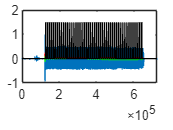


figure;
plot(output_track);
hold on;
plot(power_debug,'r');
plot(syncPower_debug,'g');
plot(start_index_debug,'black');
hold off;


% 打开文件（'w'表示写入模式）
fileID = fopen('output.txt', 'w');
% 使用 fprintf 将数组写入文件，每个数字之间用空格分隔
fprintf(fileID, '%g ', decode_result);
% 关闭文件
fclose(fileID);